Loading files to be analyzed and declaring variables

clear;close all;clc;
PPdata1=PPdataClass;PPdata2=PPdataClass;PPdata3=PPdataClass;
PPdata4=PPdataClass;PPdata5=PPdataClass;PPdata6=PPdataClass;
PPdata7=PPdataClass;PPdata8=PPdataClass;

%add/remove % sign for the correct number of PPdata to analyze
PPdata1.loadPPdata('Cond1_1.xls','Cond1_2.xls','Cond1_3.xls');
PPdata2.loadPPdata('Cond2_1.xls','Cond2_2.xls','Cond2_3.xls');
PPdata3.loadPPdata('Cond3_1.xls','Cond3_2.xls','Cond3_3.xls')
PPdata4.loadPPdata('Cond4_1.xls','Cond4_2.xls','Cond4_3.xls');
PPdata5.loadPPdata('Cond5_1.xls','Cond5_2.xls','Cond5_3.xls');
PPdata6.loadPPdata('Cond6_1.xls','Cond6_2.xls','Cond6_3.xls');
%PPdata7.loadPPdata('Cond7_1.xls','Cond7_2.xls','Cond7_3.xls');
%PPdata8.loadPPdata('Cond8_1.xls','Cond8_2.xls','Cond8_3.xls');

Plotting cumulative distribution for Frequency

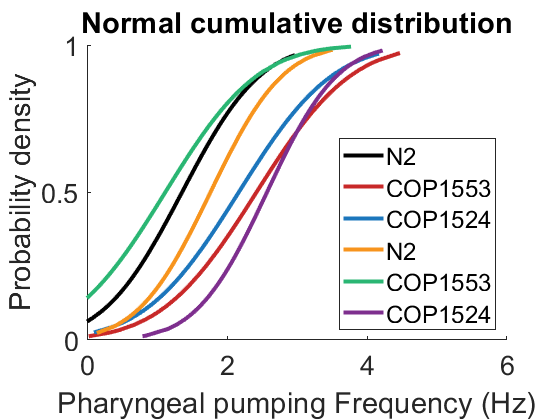

freqCDFplot=plot(PPdata1.freqSorted,PPdata1.freqCDF,'Color','#000000','LineWidth',3);
hold on
plot(PPdata2.freqSorted,PPdata2.freqCDF,'Color','#C82929','LineWidth',3);
plot(PPdata3.freqSorted,PPdata3.freqCDF,'Color','#1C76BC','LineWidth',3);
plot(PPdata4.freqSorted,PPdata4.freqCDF,'Color','#F7941D','LineWidth',3);
plot(PPdata5.freqSorted,PPdata5.freqCDF,'Color','#2AB673','LineWidth',3);
plot(PPdata6.freqSorted,PPdata6.freqCDF,'Color','#7E2F8E','LineWidth',3);
plot(PPdata7.freqSorted,PPdata7.freqCDF,'Color','#77AC30','LineWidth',3);
plot(PPdata8.freqSorted,PPdata8.freqCDF,'Color','#D95319','LineWidth',3);
xlabel("Pharyngeal pumping Frequency (Hz)",'FontSize',30);
ylabel("Probability density",'FontSize',28);
title('Normal cumulative distribution');
set(gca,'box','off','FontSize',20);
axis ([0 6 0 1]);

%add PPdataX.name (8 max.) to the legend below
legend(PPdata1.name,PPdata2.name,PPdata3.name,PPdata4.name,PPdata5.name,PPdata6.name,"Location","southeast");
saveas(gcf,'output-PP_Frequency.pdf');
hold off

Data table output

%add/remove % sign for the correct number of PPdata to analyze
PPdata1.tableoutput('output-PPdata1.csv');
PPdata2.tableoutput('output-PPdata2.csv');
PPdata3.tableoutput('output-PPdata3.csv');
PPdata4.tableoutput('output-PPdata4.csv');
PPdata5.tableoutput('output-PPdata5.csv');
%PPdata6.tableoutput('output-PPdata6.csv');
%PPdata7.tableoutput('output-PPdata7.csv');
%PPdata8.tableoutput('output-PPdata8.csv');

Two-sample Kolgomorov-Smirnoff test to compare two Freq distributions and assess if they are different.

%Add PPdataX.freq to tablefreq when n=90 for statistical test
tablefreq=[PPdata1.freq,PPdata2.freq,PPdata3.freq];
count=1;tablestat={zeros(28,4)};
for n=1:(size(tablefreq,2))
    for m=1:(size(tablefreq,2)-n)
        [stat_output,p_value,k_value]=kstest2(rmoutliers(tablefreq(:,n),'mean'),rmoutliers(tablefreq(:,(n+m)),'mean'));
        count=count+1;
        if stat_output==1
            tablestat(count,:)={[join([num2str(n),"vs",num2str(n+m)]);"True";p_value;k_value]};
        else
            tablestat(count,:)={[join([num2str(n),"vs",num2str(n+m)]);"False";p_value;k_value]};
        end
    end
end
clear n m p_value k_value count stat_output;
tablestat(1,:)={["Comparison";"Significant ?";"p-value";"k_value"]};
writetable(cell2table(tablestat),"output-table_stat_Frequency.csv");

Plotting Pump Model

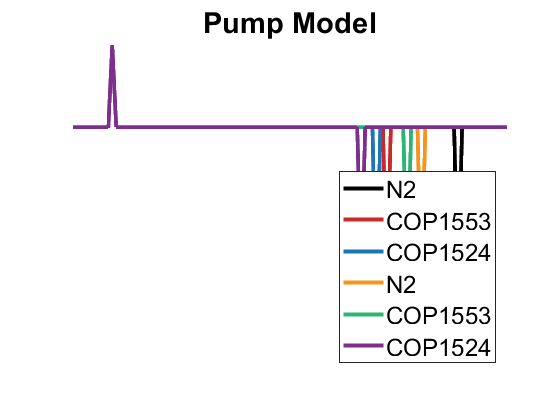

%add/remove % sign for the correct number of PPdataX
plot(PPdata1.pumpModel,'Color','#000000','LineWidth',3);
hold on
plot(PPdata2.pumpModel,'Color','#C82929','LineWidth',3);
plot(PPdata3.pumpModel,'Color','#1C76BC','LineWidth',3);
plot(PPdata4.pumpModel,'Color','#F7941D','LineWidth',3);
plot(PPdata5.pumpModel,'Color','#2AB673','LineWidth',3);
plot(PPdata6.pumpModel,'Color','#7E2F8E','LineWidth',3);
%plot(PPdata7.pumpModel,'Color','#77AC30','LineWidth',3);
%plot(PPdata8.pumpModel,'Color','#D95319','LineWidth',3);
title('Pump Model'); axis off;
set(gca,'box','off','FontSize',20);

%add PPdataX.name (8 max.) to the legend below
legend(PPdata1.name,PPdata2.name,PPdata3.name,PPdata4.name,PPdata5.name,PPdata6.name,"Location","southeast")
saveas(gcf,'PumpModel.pdf');
hold off

Statistical test for Pump Model (Welch's unequal variance t-test)

%Add PPdataX.meanDur when n=90 for statistical test
tablemeanDur=[PPdata1.meanDur,PPdata2.meanDur,PPdata3.meanDur];
count=1;tablestatmeanDur={zeros(28,4)};
for n=1:(size(tablemeanDur,2))
    for m=1:(size(tablemeanDur,2)-n)
        [stat_output,p_value]=ttest2(rmoutliers(tablemeanDur(:,n),'mean'),rmoutliers(tablemeanDur(:,(n+m)),'mean'),'vartype','unequal');
        count=count+1;
        if stat_output==1
            tablestatmeanDur(count,:)={[join([num2str(n),"vs",num2str(n+m)]);"True";p_value]};
        else
            tablestatmeanDur(count,:)={[join([num2str(n),"vs",num2str(n+m)]);"False";p_value]};
        end
    end
end
clear n m p_value count stat_output;
tablestatmeanDur(1,:)={["Comparison";"Significant ?";"p-value"]};
writetable(cell2table(tablestatmeanDur),"output-table_stat_pump-duration.csv");

Plotting InterPump Model

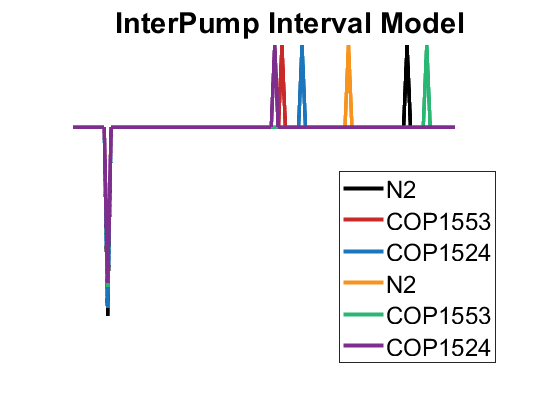

%add/remove % sign for the correct number of PPdataX
plot(PPdata1.IPIModel,'Color','#000000','LineWidth',3);
hold on
plot(PPdata2.IPIModel,'Color','#C82929','LineWidth',3);
plot(PPdata3.IPIModel,'Color','#1C76BC','LineWidth',3);
plot(PPdata4.IPIModel,'Color','#F7941D','LineWidth',3);
plot(PPdata5.IPIModel,'Color','#2AB673','LineWidth',3);
plot(PPdata6.IPIModel,'Color','#7E2F8E','LineWidth',3);
%plot(PPdata7.IPIModel,'Color','#77AC30','LineWidth',3);
%plot(PPdata8.IPIModel,'Color','#D95319','LineWidth',3);
title('InterPump Interval Model'); axis off;
set(gca,'box','off','FontSize',20);

%add PPdataX.name (8 max.) to the legend below
legend(PPdata1.name,PPdata2.name,PPdata3.name,PPdata4.name,PPdata5.name,PPdata6.name,"Location","southeast")
saveas(gcf,'InterPumpIntervalModel.pdf');
hold off

Pump mean and Std dev

tablemean=["" "" "" "" "" "" "" "" "" ; ...
    "Mean" mean(PPdata1.TotalPump) mean(PPdata2.TotalPump) mean(PPdata3.TotalPump) mean(PPdata4.TotalPump) ...
    mean(PPdata5.TotalPump) mean(PPdata6.TotalPump) mean(PPdata7.TotalPump) mean(PPdata8.TotalPump); ...
    "Std dev" std(PPdata1.TotalPump) std(PPdata2.TotalPump) std(PPdata3.TotalPump) std(PPdata4.TotalPump) ...
    std(PPdata5.TotalPump) std(PPdata6.TotalPump) std(PPdata7.TotalPump) std(PPdata8.TotalPump)];

%add/remove % sign for the correct number of PPdataX
tablemean(1,2) = [convertCharsToStrings(PPdata1.name)];
tablemean(1,3) = [convertCharsToStrings(PPdata2.name)];
tablemean(1,4) = [convertCharsToStrings(PPdata3.name)];
tablemean(1,5) = [convertCharsToStrings(PPdata4.name)];
tablemean(1,6) = [convertCharsToStrings(PPdata5.name)];
tablemean(1,7) = [convertCharsToStrings(PPdata6.name)];
%tablemean(1,8) = [convertCharsToStrings(PPdata7.name)];
%tablemean(1,9) = [convertCharsToStrings(PPdata8.name)];

writematrix(tablemean, "PumpMeanStdDev.csv");
clear tablemean;

Interpump mean and Std dev

tablemean=["" "" "" "" "" "" "" "" "" ; ...
    "Mean" mean(PPdata1.TotalIPI) mean(PPdata2.TotalIPI) mean(PPdata3.TotalIPI) mean(PPdata4.TotalIPI) ...
    mean(PPdata5.TotalIPI) mean(PPdata6.TotalIPI) mean(PPdata7.TotalIPI) mean(PPdata8.TotalIPI); ...
    "Std dev" std(PPdata1.TotalIPI) std(PPdata2.TotalIPI) std(PPdata3.TotalIPI) std(PPdata4.TotalIPI) ...
    std(PPdata5.TotalIPI) std(PPdata6.TotalIPI) std(PPdata7.TotalIPI) std(PPdata8.TotalIPI)];

%add/remove % sign for the correct number of PPdataX
tablemean(1,2) = [convertCharsToStrings(PPdata1.name)];
tablemean(1,3) = [convertCharsToStrings(PPdata2.name)];
tablemean(1,4) = [convertCharsToStrings(PPdata3.name)];
tablemean(1,5) = [convertCharsToStrings(PPdata4.name)];
tablemean(1,6) = [convertCharsToStrings(PPdata5.name)];
tablemean(1,7) = [convertCharsToStrings(PPdata6.name)];
%tablemean(1,8) = [convertCharsToStrings(PPdata7.name)];
%tablemean(1,9) = [convertCharsToStrings(PPdata8.name)];

writematrix(tablemean, "IPIMeanStdDev.csv");
clear tablemean;

Pump distribution (need to remove zeroes in the excel sheet obtained)

tablelength = max(cellfun(@numel, {PPdata1.TotalPump,PPdata2.TotalPump,PPdata3.TotalPump,PPdata4.TotalPump,PPdata5.TotalPump,PPdata6.TotalPump,PPdata7.TotalPump,PPdata8.TotalPump}));
tablemeanpumpdur = zeros(tablelength, 8);
tablename = ["","","","","","","",""];

%add/remove % sign for the correct number of PPdata to analyze
tablemeanpumpdur(1:length(PPdata1.TotalPump),1) = [PPdata1.TotalPump]; tablename(1) = [convertCharsToStrings(PPdata1.name)];
tablemeanpumpdur(1:length(PPdata2.TotalPump),2) = [PPdata2.TotalPump]; tablename(2) = [convertCharsToStrings(PPdata2.name)];
tablemeanpumpdur(1:length(PPdata3.TotalPump),3) = [PPdata3.TotalPump]; tablename(3) = [convertCharsToStrings(PPdata3.name)];
tablemeanpumpdur(1:length(PPdata4.TotalPump),4) = [PPdata4.TotalPump]; tablename(4) = [convertCharsToStrings(PPdata4.name)];
tablemeanpumpdur(1:length(PPdata5.TotalPump),5) = [PPdata5.TotalPump]; tablename(5) = [convertCharsToStrings(PPdata5.name)];
tablemeanpumpdur(1:length(PPdata6.TotalPump),6) = [PPdata6.TotalPump]; tablename(6) = [convertCharsToStrings(PPdata6.name)];
%tablemeanpumpdur(1:length(PPdata7.TotalPump),7) = [PPdata7.TotalPump]; tablename(7) = [convertCharsToStrings(PPdata7.name)];
%tablemeanpumpdur(1:length(PPdata8.TotalPump),8) = [PPdata8.TotalPump]; tablename(8) = [convertCharsToStrings(PPdata8.name)];

%add PPdataX.name (8 max) in the table below
cellmeanpumpdur = [cellstr(tablename);num2cell(tablemeanpumpdur)];
writecell(cellmeanpumpdur,"output-table_pumpDurTotal.csv");
clear tablemeanpumpdur tablelength cellmeanpumpdur;

Interpump distribution (need to remove zeroes in the excel sheet obtained)

tablelength = max(cellfun(@numel, {PPdata1.TotalIPI,PPdata2.TotalIPI,PPdata3.TotalIPI,PPdata4.TotalIPI,PPdata5.TotalIPI,PPdata6.TotalIPI,PPdata7.TotalIPI,PPdata8.TotalIPI}));
tablemeanIPIdur = zeros(tablelength, 8);

%add/remove % sign for the correct number of PPdata to analyze
tablemeanIPIdur(1:length(PPdata1.TotalIPI),1) = [PPdata1.TotalIPI]; tablename(1) = [convertCharsToStrings(PPdata1.name)];
tablemeanIPIdur(1:length(PPdata2.TotalIPI),2) = [PPdata2.TotalIPI]; tablename(2) = [convertCharsToStrings(PPdata2.name)];
tablemeanIPIdur(1:length(PPdata3.TotalIPI),3) = [PPdata3.TotalIPI]; tablename(3) = [convertCharsToStrings(PPdata3.name)];
tablemeanIPIdur(1:length(PPdata4.TotalIPI),4) = [PPdata4.TotalIPI]; tablename(4) = [convertCharsToStrings(PPdata4.name)];
tablemeanIPIdur(1:length(PPdata5.TotalIPI),5) = [PPdata5.TotalIPI]; tablename(5) = [convertCharsToStrings(PPdata5.name)];
tablemeanIPIdur(1:length(PPdata6.TotalIPI),6) = [PPdata6.TotalIPI]; tablename(6) = [convertCharsToStrings(PPdata6.name)];
%tablemeanIPIdur(1:length(PPdata7.TotalIPI),7) = [PPdata7.TotalIPI]; tablename(7) = [convertCharsToStrings(PPdata7.name)];
%tablemeanIPIdur(1:length(PPdata8.TotalIPI),8) = [PPdata8.TotalIPI]; tablename(8) = [convertCharsToStrings(PPdata8.name)];

%add PPdataX.name (8 max) in the table below
cellmeanIPIdur = [cellstr(tablename);num2cell(tablemeanIPIdur)];
writecell(cellmeanIPIdur,"output-table_IPIDurTotal.csv");
clear tablemeanIPIdur tablelength tablename cellmeanIPIdur;

Statistical test for InterPump Interval Model (Welch's unequal variance t-test)

%Add PPdataX.IPIDur when n=90 for statistical test
tableIPIDur=[PPdata1.IPIDur,PPdata2.IPIDur,PPdata3.IPIDur];
count=1;tablestatIPIDur={zeros(28,4)};
for n=1:(size(tableIPIDur,2))
    for m=1:(size(tableIPIDur,2)-n)
        [stat_output,p_value]=ttest2(rmoutliers(tableIPIDur(:,n),'mean'),rmoutliers(tableIPIDur(:,(n+m)),'mean'),'vartype','unequal');
        count=count+1;
        if stat_output==1
            tablestatIPIDur(count,:)={[join([num2str(n),"vs",num2str(n+m)]);"True";p_value]};
        else
            tablestatIPIDur(count,:)={[join([num2str(n),"vs",num2str(n+m)]);"False";p_value]};
        end
    end
end
clear n m p_value count stat_output;
tablestatIPIDur(1,:)={["Comparison";"Significant ?";"p-value"]};
writetable(cell2table(tablestatIPIDur),"output-table_stat_IPI-duration.csv");

Plotting pump duration probability density function histogram

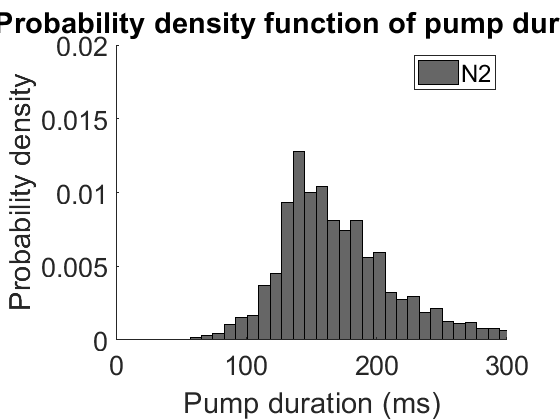

pumpPDFHist(PPdata1.name,PPdata1.TotalPump,'#000000','PPdata1-pumpDistHist.pdf')

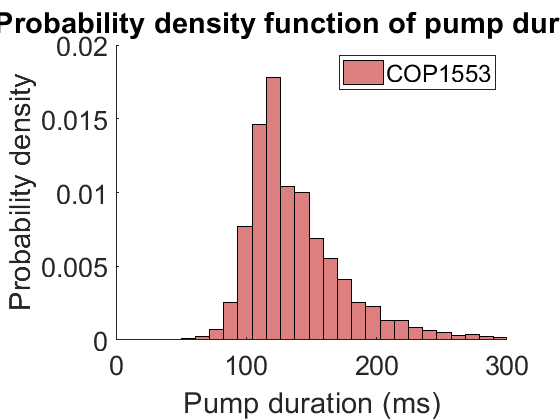

pumpPDFHist(PPdata2.name,PPdata2.TotalPump,'#C82929','PPdata2-pumpDistHist.pdf')

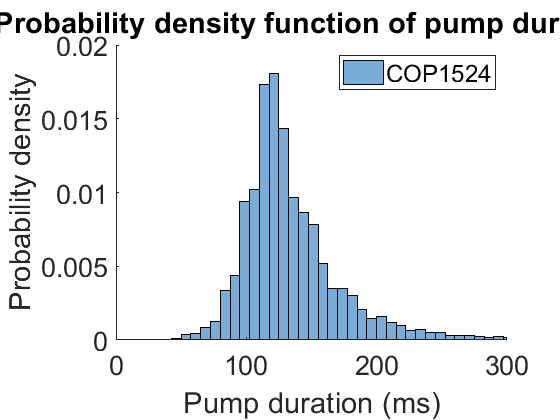

pumpPDFHist(PPdata3.name,PPdata3.TotalPump,'#1C76BC','PPdata3-pumpDistHist.pdf')

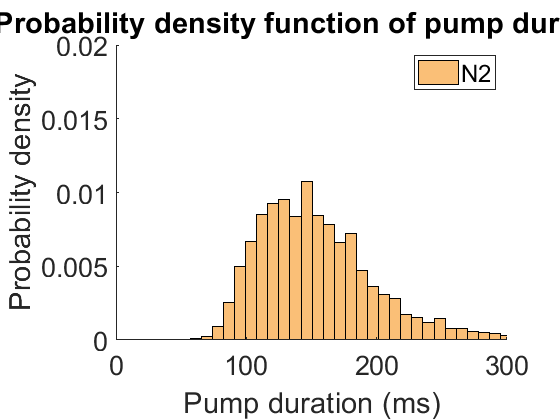

pumpPDFHist(PPdata4.name,PPdata4.TotalPump,'#F7941D','PPdata4-pumpDistHist.pdf')

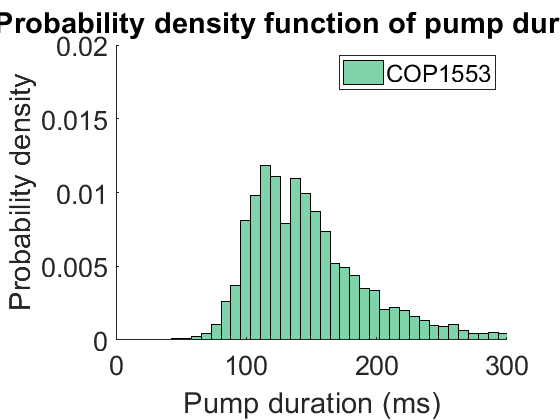

pumpPDFHist(PPdata5.name,PPdata5.TotalPump,'#2AB673','PPdata5-pumpDistHist.pdf')

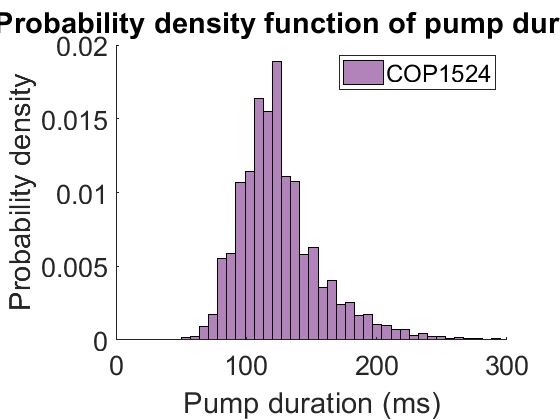

pumpPDFHist(PPdata6.name,PPdata6.TotalPump,'#7E2F8E','PPdata6-pumpDistHist.pdf')

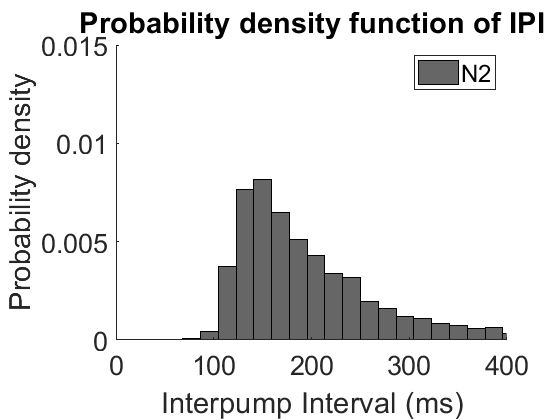

%pumpPDFHist(PPdata7.name,PPdata7.TotalPump,'#77AC30','PPdata7-pumpDistHist.pdf')
%pumpPDFHist(PPdata8.name,PPdata8.TotalPump,'#D95319','PPdata8-pumpDistHist.pdf')

IPIPDFHist(PPdata1.name,PPdata1.TotalIPI,'#000000','PPdata1-IPIDistHist.pdf')

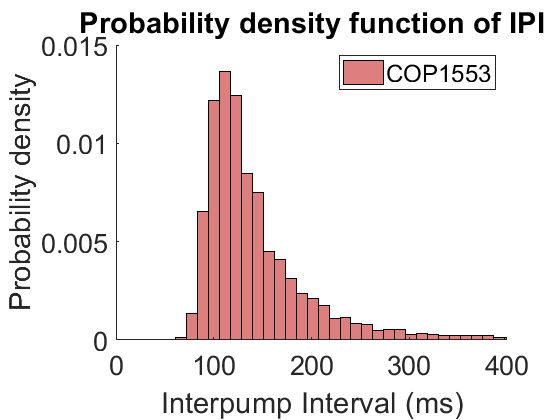

IPIPDFHist(PPdata2.name,PPdata2.TotalIPI,'#C82929','PPdata2-IPIDistHist.pdf')

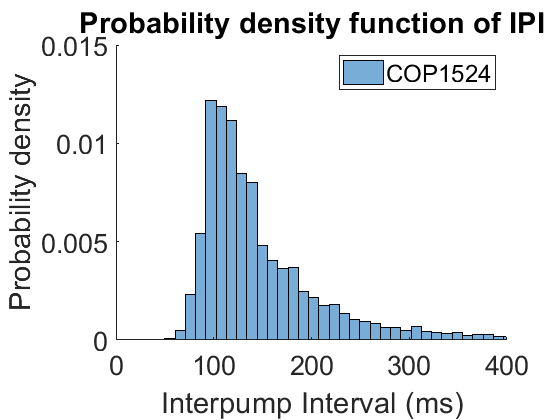

IPIPDFHist(PPdata3.name,PPdata3.TotalIPI,'#1C76BC','PPdata3-IPIDistHist.pdf')

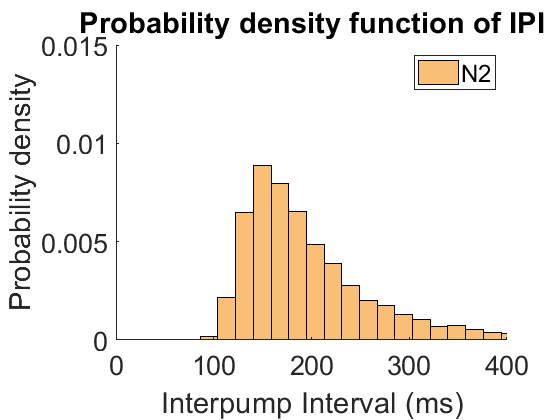

IPIPDFHist(PPdata4.name,PPdata4.TotalIPI,'#F7941D','PPdata4-IPIDistHist.pdf')

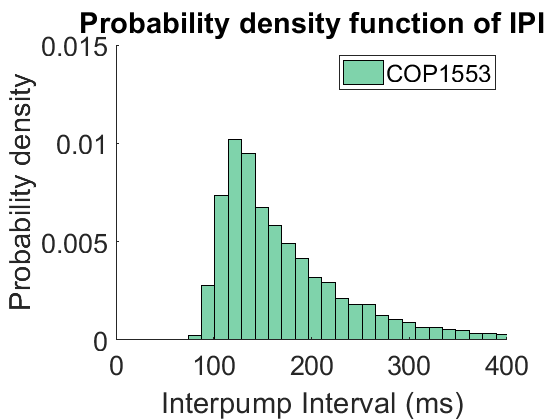

IPIPDFHist(PPdata5.name,PPdata5.TotalIPI,'#2AB673','PPdata5-IPIDistHist.pdf')

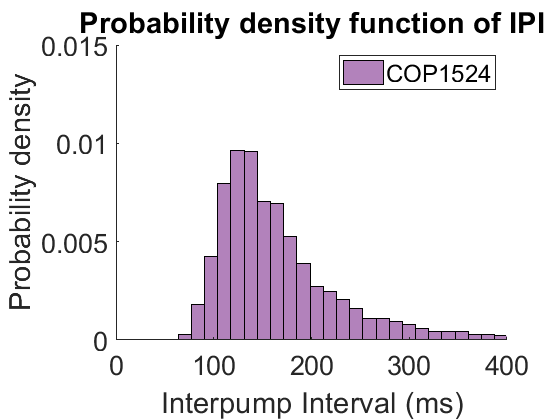

IPIPDFHist(PPdata6.name,PPdata6.TotalIPI,'#7E2F8E','PPdata6-IPIDistHist.pdf')

%IPIPDFHist(PPdata7.name,PPdata7.TotalIPI,'#77AC30','PPdata7-IPIDistHist.pdf')
%IPIPDFHist(PPdata8.name,PPdata8.TotalIPI,'#D95319','PPdata8-IPIDistHist.pdf')

Function for probability density histogram (pump duration)

function pumpPDFHist(legendPPdata,dataTotalPump,color,name)
    histogram(dataTotalPump,'Normalization',"pdf","NumBins",60,"FaceColor",color);
    hold on
    axis ([0 300 0 0.020]);
    xlabel("Pump duration (ms)",'FontSize',30);
    ylabel("Probability density",'FontSize',28);
    title('Probability density function of pump duration');
    set(gca,'box','off','FontSize',20);
    legend(legendPPdata,"Location","northeast");
    saveas(gcf,name);
    hold off
end

Function for probability density histogram (InterPump Interval)

function IPIPDFHist(legendPPdata,dataTotalIPI,color,name)
    histogram(dataTotalIPI,'Normalization',"pdf","NumBins",60,"FaceColor",color);
    hold on
    axis ([0 400 0 0.015]);
    xlabel("Interpump Interval (ms)",'FontSize',30);
    ylabel("Probability density",'FontSize',28);
    title('Probability density function of IPI');
    set(gca,'box','off','FontSize',20);
    legend(legendPPdata,"Location","northeast");
    saveas(gcf,name);
    hold off
end